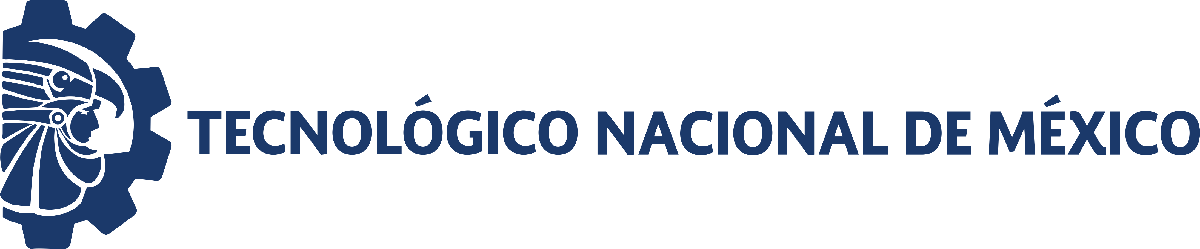                                 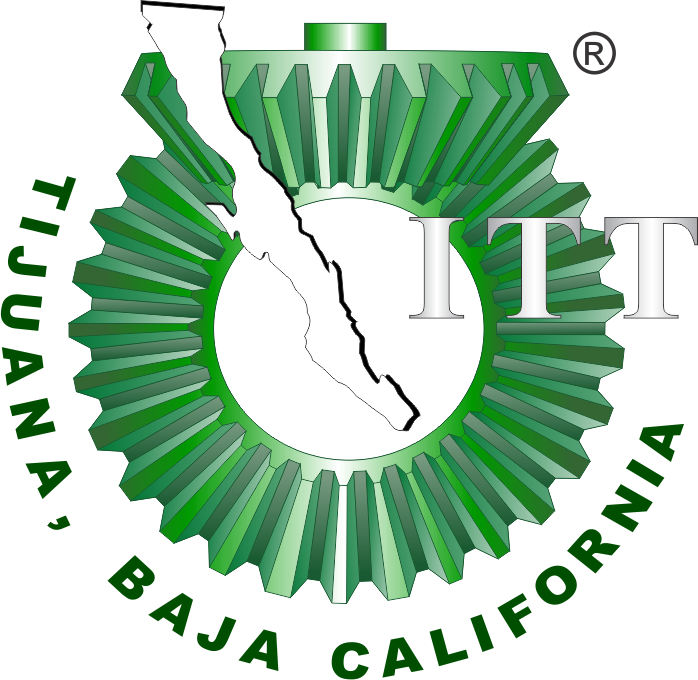

# Proyecto Final: Mecanica Pulmonar-Asma

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

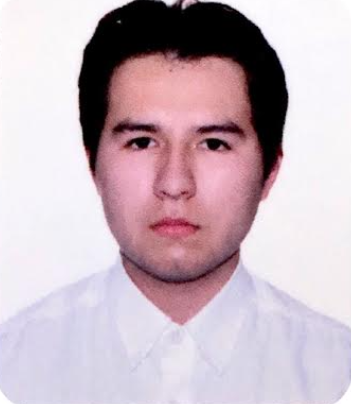

Nombre del alumno: Juarez Salazar Angel Eduardo

Número de control: 22210417

Correo institucional: L22210417@tectijuana.edu.mx

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '30'; 
file = 'ProyectoFinalLC';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';
Controlador = 'PID'; 

## Rendimiento del controlador

kP=Rr/Re

kl= 1/ReCr

kD=RrCe

Settling time= 0.00226

Overshoot= 0.705%

Peak=  1.01

## Comparacion de Respiracion 

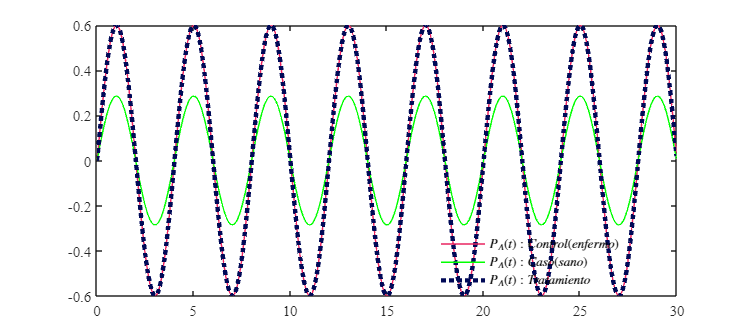

Signal = 'Respiracion normal';
set_param('ProyectoFinalLC/PID Controller','P','1382.64108107363');
set_param('ProyectoFinalLC/PID Controller','I','23976.1659464632');
set_param('ProyectoFinalLC/PID Controller','D','7.06671657792426');
N = sim(file,parameters);
plotsignals(N.t,N.PAx,N.PAy,N.PAz,Signal)

## Funcion:Respuesta a las señales

function plotsignals(t,PA,Pao,PID, Signal)
set(figure(),'Color','w')
set(gcf,'Units','Centimeters','Position',[1,1,18,8])
set(gca,'FontName','Times New Roman')
fontsize(10,'points')
red = [232/255, 37/255,97/255];
blueR = [0, 9/255, 87/255];
green = [0, 255/255, 0];
hold on; grid off; box on;

plot(t,PA,'LineWidth',1,'Color',red)
plot(t,Pao,'LineWidth',1,'Color',green)
plot(t,PID,':','LineWidth',3,'Color',blueR)

L= legend('$P_{A}(t):Control(enfermo)$','$P_{A}(t):Caso(sano)$','$P_{A}(t):Tratamiento$');
set(L, 'Interpreter','Latex','Location','Best','Box','off')

end
